# DSZOB, cvičenie 4.

## **Zadanie:**

## **Úloha 1 - **Analýza signálu

**Nasnímajte signál zvuku ladičky. **

Vizualizujte nasnímaný signál v priestorovej doméne. Na základe vizualizácie vyberte vhodný úsek, vypočítajte a vizualizujte preň Fourierovu transformáciu:

- Cez funkciu **fft** na malej vzorke dát (napr. 512)

- Prepočítajte index spektrálneho koeficienta na frekvenciu pre najväčsiu hodnotu v grafe

- Cez funkciu **spectrogram**

- Zistite dominantnú frekvenciu daného signálu a vyznačte ju v grafe.

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

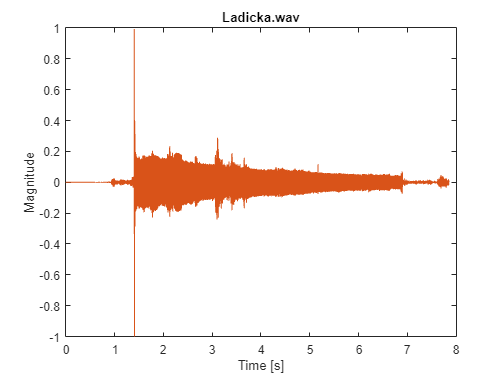

clear
fork = audioread("Asignments\Assignment_3\ladicka.wav");
fork_info = audioinfo("Asignments\Assignment_3\ladicka.wav");
fs = fork_info.SampleRate;
time_axis = 0:1/fs:fork_info.Duration;
time_axis(end) = [];    % Fix for rounding issue
plot(time_axis, fork);
title("Ladicka.wav")
xlabel("Time [s]");
ylabel("Magnitude")

fork_sample = fork(fs*2: fs*2 + 511, 1);    % 512 samples after second second
length(fork_sample)

ans = 512

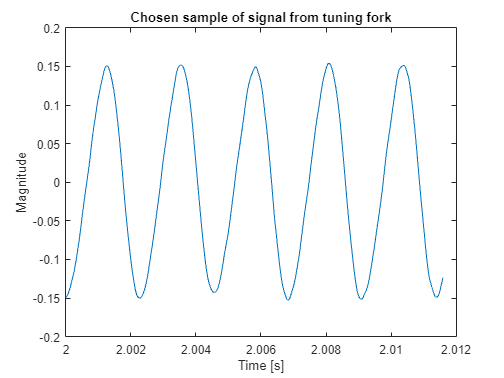

time_axis_sample = 2:1/fs:2+(1/fs) * 511;
plot(time_axis_sample, fork_sample);
title("Chosen sample of signal from tuning fork")
xlabel("Time [s]");
ylabel("Magnitude");

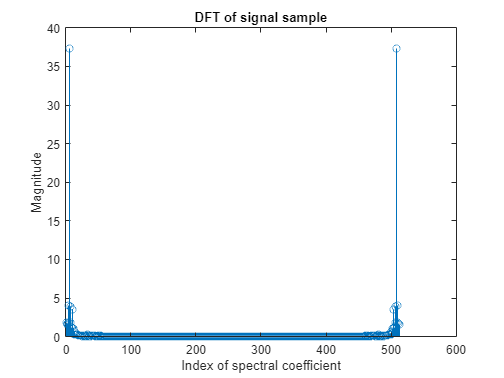

fork_dft = fft(fork_sample);
stem(abs(fork_dft));
xlabel("Index of spectral coefficient");
title("DFT of signal sample");
ylabel("Magnitude");

Highest index -1 to accomodate dc component, divided by number of samples halved, multiplied by sampling rate halved to get rough frequency of sample, result is 430 Hz.

fq = (5/(length(fork_sample)/2)) * (fs/2)

fq = 430.6641

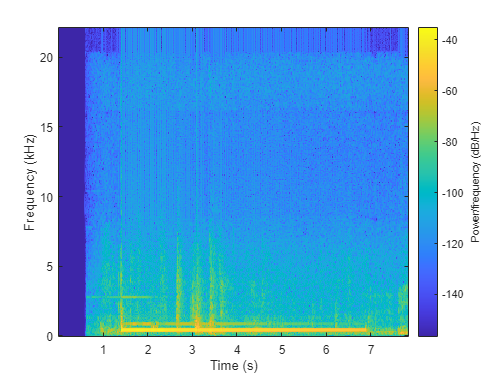

spectrogram(fork(:,1), 512, 256 , 512, fs, "yaxis");

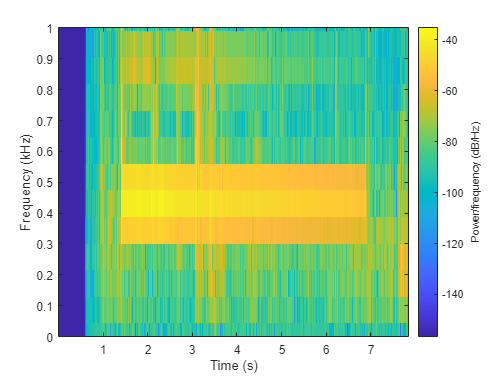

spectrogram(fork(:,1), 512, 256 , 512, fs, "yaxis");
ylim([0, 1]);

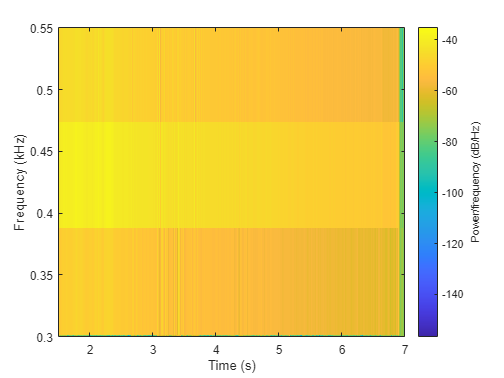

spectrogram(fork(:,1), 512, 256 , 512, fs, "yaxis");
ylim([0.3, 0.55]);
xlim([1.5, 7]);

## **Úloha 2 - Zero Padding v spektrálnej doméne**

Vygenerujte si náhodne zložený signál s dĺžkou 1 sekunda a s voľne zvolenou malou vzorkovacou frekvenciou. Zvolte si parametre signálu tak, aby najväčšia frekvencia generovaného signálu neprekročila 16Hz a vzorkovacia frekvencia pod 64Hz. Dbajte pri tom na to, aby bol splnený Nyquistov teorém. 

Vykonajte zero padding signálu v spektrálnej doméne tak, že doplníte nulami spektrum od jeho stredu (stred symetrie musí ostať zachovaný). Doplnenie vykonajte na velkosť vzorky 1024. Následne vykonajte spätnú transformáciu do časovej domény. Pôvodný signál, ako aj novo vytvorený spoločne vizualizujte v jednom grafe, kde x-os bude reprezentovať čas v rozsahu 1 sek.

Zodpovedajte nasledovné otázky:

- Akú výhodu nam priniesol zero padding v spektre?

- Vie nám zero padding v spektre pomôcť v prípade, ak bol porušený Nyquistov teorém v pôvodnom signále? (áno/nie)

## Pomôcky:

- complex()

- zeros()

- ifft()

## Poznámka:

- Spektrum signálu obsahuje magnitúdovú aj fázovú zložku. Pri dopĺňaní spektra nulami teda pracujeme s komplexnými číslami (0 + 0*i)

- Po spätnom prepočte inverznej transformacie prenásobte výsledný signál konštantou 1024/Fs pre normalizáciu hodnôt na veľkosť okienka

## **Riešenie:**

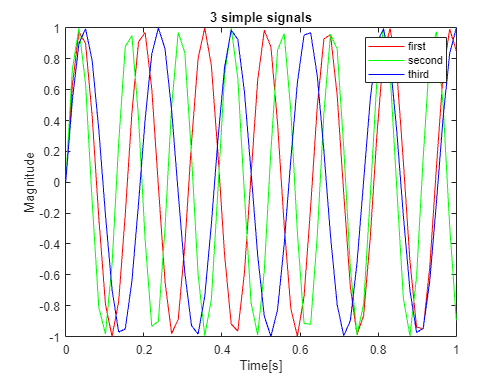

frequency = 59;
time_axis = 0:1/frequency:1;

first = 8 * rand();
second = 8 * rand();
third = 8 * rand();

% nquist law always abided, with sampling rate of 59 and highest ferquency
% being 8, the minimum sample per period is 7

frequency_1 = first * 2 * pi;
frequency_2 = second * 2 * pi;
frequency_3 = third * 2 * pi;
sig_1 = sin(time_axis * frequency_1);
sig_2 = sin(time_axis * frequency_2); 
sig_3 = sin(time_axis * frequency_3); 

plot(time_axis, sig_1, "red");  hold on
plot(time_axis, sig_2, "green");
plot(time_axis, sig_3, "blue");
xlabel("Time[s]");
ylabel("Magnitude");
title("3 simple signals");
legend("first", "second", "third");
hold off

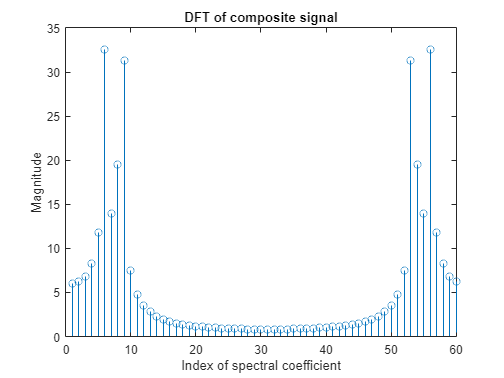

composite = sig_1 + sig_2 + sig_3;
composite_dft = fft(composite);
stem(abs(composite_dft));
title("DFT of composite signal")
ylabel("Magnitude")
xlabel("Index of spectral coefficient")

dft_len = length(composite_dft)

dft_len = 60

padded = [complex(composite_dft(1,1:30)),complex(zeros(1, 1024 - length(time_axis))), complex(composite_dft(1,31:60))];
length(ifft(padded))

ans = 1024

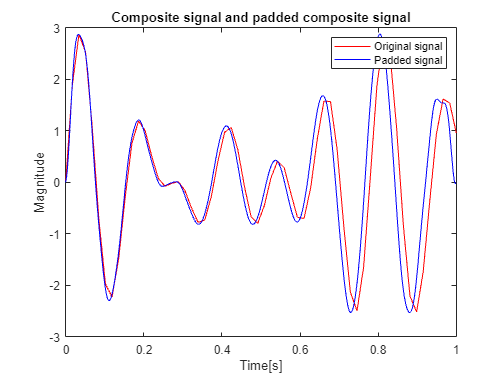

plot(time_axis, composite, "red"); hold on
plot([0:1/1024: 1 - 1/1024], real(ifft(padded) * (1024/60)), "blue"); 
xlabel("Time[s]");
ylabel("Magnitude");
title("Composite signal and padded composite signal");
legend("Original signal", "Padded signal");
hold off

**Answer: **Padding lowers the magnitude of our new signal compared to the original signal, but it retains its direction. By multiplying the new signal by new_samplesize/original_samplesize we get an estimate of what the signal would look like with a higher sampling rate. Zero padding can't help in a broken nyquist theorem situation because the local extremes are already wrongly captured, therefore the estimate of higher sampling rate will be wrong too.